## Import the data

#### Import CSV file

clearvars;
filename = ['../Data/Ron_50_Roff_50' ...
    '/Pulse_60_Vds_350_Vgson_175_Vgsoff_30_ALL_20230425140645918.csv']

filename = '../Data/Ron_50_Roff_50/Pulse_60_Vds_350_Vgson_175_Vgsoff_30_ALL_20230425140645918.csv'

data = readtable(filename);

#### Data parsing

data = renamevars(data, "Labels", "Time");
t = data.Time;
Vgs = data.Vgs;
Vds = data.Vds;
Id = data.Id; 

## Plot the imported data

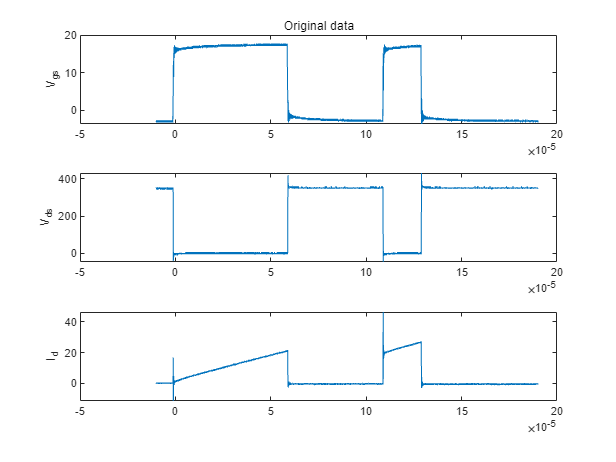

figure;

subplot(3,1,1);
plot(t, Vgs);
ylabel("V_{gs}");
title("Original data");

subplot(3,1,2);
plot(t, Vds);
ylabel("V_{ds}");

subplot(3,1,3);
plot(t, Id);
ylabel("I_d");

## Find the switching transient

#### Eliminate the mean value in Vds

to find the switching transient by means of finding the zerocrossing of Vds waveform.

Vds_mean = mean(Vds)

Vds_mean = 210.5149

Vds_zeromean = Vds - Vds_mean;

#### Find the zerocrossing

min_gap = 10000; % Arbitrary value

zero_crossings = Find_zeroCrossing(Vds_zeromean, min_gap);
assert(length(zero_crossings) == 4, "Error: Switching transient detection failed")

% Interpolate the time values corresponding to the zero crossings
zero_crossing_times = interp1(1:length(t), t, zero_crossings);
clear zero_crossings

#### Parse the zerocrossing point to switching transient

zero_crossing_names = {"Charging"; "Turn-Off"; "Turn-On"; "End"}

zero_crossing_names = 4×1 cell 배열
    {["Charging"]}
    {["Turn-Off"]}
    {["Turn-On" ]}
    {["End"     ]}


st_time = containers.Map();
for i = 1:4
    st_time(zero_crossing_names{i}) = zero_crossing_times(i);
end
clear i
disp(keys(st_time))

    {'Charging'}    {'End'}    {'Turn-Off'}    {'Turn-On'}



disp(values(st_time))

    {[-1.1154e-06]}    {[1.2894e-04]}    {[5.8951e-05]}    {[1.0889e-04]}



#### Plot the zerocrossing 

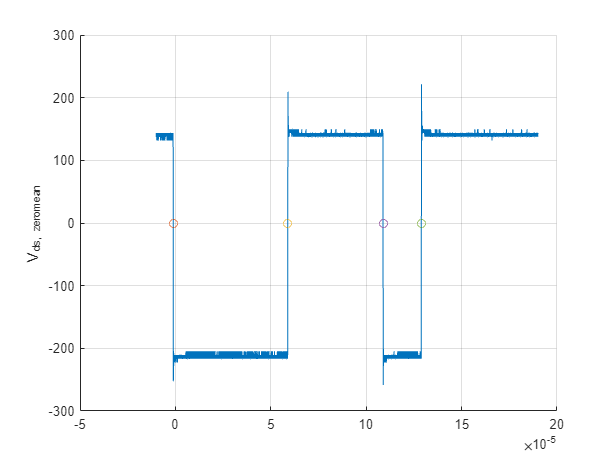

figure;
hold on;
plot(t, Vds_zeromean);
scatter(zero_crossing_times, 0);
ylabel("V_{ds, zeromean}");
grid on;
hold off;

clear zero_crossing_times zero_crossing_names
clear Vds_mean Vds_zeromean
clear min_gap

#### Find the switching transients

fs = length(t)/(t(length(t)) - t(1));
testTime = 1.392e-6; % seconds  % To be test length 8700
% testTime = 4.0e-6; % seconds  % 
testLength = floor(fs * testTime + eps)

testLength = 8700

st_time_range_turnoff_offset = -0.2e-6;
st_time_range_turnon_offset = -0.2e-6;


st_time_range_turnoff = [0 testTime] + st_time_range_turnoff_offset;
st_time_range_turnon = [0 testTime] + st_time_range_turnon_offset;

st_time_range_turnoff = st_time_range_turnoff + eps;
st_time_range_turnon = st_time_range_turnon + eps;

Turn-Off transient

turnoff_time_search_range = st_time("Turn-Off") + st_time_range_turnoff;
index_search_turnoff = (turnoff_time_search_range(1) < t) & (t < turnoff_time_search_range(2));

% Id_search_turnoff = Id(index_search_turnoff);
% min_gap = 10000; % Arbitrary value
% t_search_turnoff_zcIndex = floor(Find_zeroCrossing(Id_search_turnoff, min_gap));
% t_search_turnoff_startIndex = find(index_search_turnoff, 1);
% t_turnoff_startIndex = t_search_turnoff_startIndex + t_search_turnoff_zcIndex;
% index_turnoff = t_turnoff_startIndex + (0:(testLength-1));

index_turnoff = index_search_turnoff;

t_turnoff = t(index_turnoff);
Vgs_turnoff = Vgs(index_turnoff);
Vds_turnoff = Vds(index_turnoff);
Id_turnoff = Id(index_turnoff);

clear turnoff_time_search_range index_search_turnoff
clear t_search_turnoff Id_search_turnoff min_gap
clear t_search_turnoff_zcIndex t_search_turnoff_startIndex t_turnoff_startIndex
clear index_turnoff

Turn-On transient 

turnon_time_search_range = st_time("Turn-On") + st_time_range_turnon;
index_search_turnon = (turnon_time_search_range(1) < t) & (t < turnon_time_search_range(2));

% Vds_search_turnon = Vds(index_search_turnon);
% min_gap = 10000; % Arbitrary value
% t_search_turnon_zcIndex = floor(Find_zeroCrossing(Vds_search_turnon, min_gap));
% t_search_turnon_startIndex = find(index_search_turnon, 1);
% t_turnon_startIndex = t_search_turnon_startIndex + t_search_turnon_zcIndex;
% index_turnon = t_turnon_startIndex + (0:(testLength-1));

index_turnon = index_search_turnon;

t_turnon = t(index_turnon);
Vgs_turnon = Vgs(index_turnon);
Vds_turnon = Vds(index_turnon);
Id_turnon = Id(index_turnon);

clear turnon_time_search_range index_search_turnon
clear t_search_turnon Vds_search_turnon min_gap
clear t_search_turnon_zcIndex t_search_turnon_startIndex t_turnon_startIndex
clear index_turnon

clear turnoff_time_search_range turnon_time_range
clear index_turnoff index_turnon
clear st_time_range

Data to table

data_turnoff = table();
data_turnoff.t = t_turnoff;
data_turnoff.Vgs = Vgs_turnoff;
data_turnoff.Vds = Vds_turnoff;
data_turnoff.Id = Id_turnoff;

data_turnon = table();
data_turnon.t = t_turnon;
data_turnon.Vgs = Vgs_turnon;
data_turnon.Vds = Vds_turnon;
data_turnon.Id = Id_turnon;

data_trs = table();
data_trs.turnoff = data_turnoff;
data_trs.turnon = data_turnon;

data_raw = table();
data_raw.t = t;
data_raw.Vgs = Vgs;
data_raw.Vds = Vds;
data_raw.Id = Id;

clear t_turnoff Vgs_turnoff Vds_turnoff Id_turnoff t_turnon Vgs_turnon Vds_turnon Id_turnon
clear t Vgs Vds Id
clear data_turnoff data_turnon

Plot at the transient

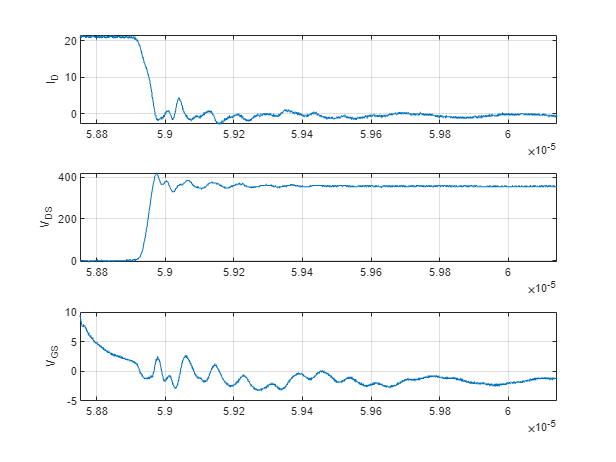

turnoff_time_range = [data_trs.turnoff.t(1) data_trs.turnoff.t(end)];
t_turnoff = data_trs.turnoff.t;
Vgs_turnoff = data_trs.turnoff.Vgs;
Vds_turnoff = data_trs.turnoff.Vds;
Id_turnoff = data_trs.turnoff.Id;

figure;
subplot(3,1,3)
plot(t_turnoff, Vgs_turnoff);
ylabel("V_{GS}");
xlim(turnoff_time_range);
grid on;
subplot(3,1,2)
plot(t_turnoff, Vds_turnoff);
ylabel("V_{DS}");
xlim(turnoff_time_range)
grid on;
subplot(3,1,1)
title("Turn-Off transient")
plot(t_turnoff, Id_turnoff);
ylabel("I_{D}");
xlim(turnoff_time_range)
grid on;

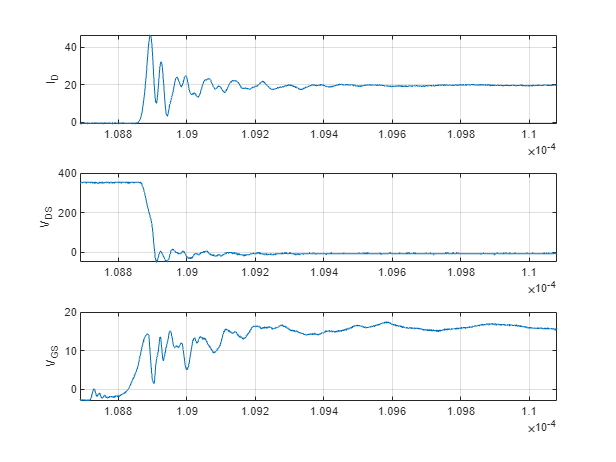

turnon_time_range = [data_trs.turnon.t(1) data_trs.turnon.t(end)];
t_turnon = data_trs.turnon.t;
Vgs_turnon = data_trs.turnon.Vgs;
Vds_turnon = data_trs.turnon.Vds;
Id_turnon = data_trs.turnon.Id;

figure;
subplot(3,1,3)
plot(t_turnon, Vgs_turnon);
ylabel("V_{GS}");
xlim(turnon_time_range)
grid on;
subplot(3,1,2)
plot(t_turnon, Vds_turnon);
ylabel("V_{DS}");
xlim(turnon_time_range)
grid on;
subplot(3,1,1)
title("Turn-On transient")
plot(t_turnon, Id_turnon);
ylabel("I_{D}");
xlim(turnon_time_range)
grid on;

clear turnoff_time_range turnon_time_range
clear t_turnoff Vgs_turnoff Vds_turnoff Id_turnoff
clear t_turnon Vgs_turnon Vds_turnon Id_turnon